## `The encounter based Markovian model and delay distribution`


loopN = 1;
nodeF = 7; %node number
iBase = 0;
jLen = 1;
jTime = 150; %int 1 delay 
kLen = 1;
kLam = 150; %int rate
lambda = cell(loopN,1);
 
ggpdf = cell(loopN, 1);

binVal = cell(loopN, 1);

conv_dly = cell(loopN, jLen, kLen);
estm_dly = cell(loopN, jLen, kLen);

conv_sto = cell(loopN, jLen, kLen);
estm_sto = cell(loopN, jLen, kLen);

gain = cell(loopN, jLen, kLen);
cost = cell(loopN, jLen, kLen);

for i = 1:loopN
%     s = 5;           %total number of nodes %5, 10, 20, 40
    s = i*nodeF+iBase;
    a = 1;            %number of consumers
    b = 0;            % O_i number of agents
    c = 1;            % N_i number of producers
    d = s -a-b-c;     %rest of the nodes
    e = s*(s-1)/2;    %number of states
    tar = 1;          %start state
    test_size = 50;  %number of steps
   
    lambda{i} = 2453.7/e;%encounter rate of all nodes 
    %lambda{i} = 2500/e;%encounter rate of all nodes 
    indexsum = cumsum(0:(s-2)); %used to transfer the index of Markov chain (O_i, N_i) to the index of transition matrix
    
    
    
    

`The following is copied from the "Modelling the Delay Distribution of Information Centric Delay Tolerant Networks in Disaster Area", you can skip this part. `

`The state transitions in the proposed ``AFSM`` are obtained as follows. Firstly, we need to note that state transitions only happen when there is an encounter between nodes. Four types of events can be identified during an encounter, namely replication of requests, replication of contents, delivery of contents and all other cases in which no replication of either contents or requests. `

`Accordingly, given a state `$\((O_i,N_i)\)$`, the following state transitions can be identified in the our ``AFSM`` model:`

- `Request Increase Transition (``RIT``): a node with request ``i`` encounters a node with neither request ``i`` nor content i. The request i is replicated to the agent. The target state is `$\((O_i,N_i)\)$` and the probability that this kind of transition occurs when two nodes encounter is `$\(P\{RIT\}=O_i(M-O_i-N_i)/M\)
$`. `

- `Content Increase Transition (``CIT``): an agent with request i encounters a node with content i. The content i is replicated to the agent. The target state is `$\((O_i-1,N_i+1)\)
$` and the probability that this kind of transition occurs when two nodes encounter is `$\(P\{CIT\}=(O_i-1)N_i/M\)$`. Because the contents are only sent to nodes with requests, `$\(N_i\)$` only increases when `$\(O_i-1>0\)$`.  `

- `Absorbing Transition (AT): the transition to state A means the successful delivery of content i and it occurs when the consumer encounters a node with content i. The probability that this kind of transition occurs when two nodes encounter is `$\(P\{AT\}=O_i/M\)$`.`

- `Self transition (ST): all other cases of encounter belong to this case. The target state is `$\((N_i, O_i)\)$`. The probability that this kind of transition occurs when two nodes encounter is `$\(P\{ST\}=(M-O_i(M-O_i))/M\)$`.`

`The transition probabilities in our AFSM model can be represented in a matrix `$\(Q\)$` \cite``{grinstead2012introduction}. As an example, the transitions in the 6 nodes ``AFSM`` model described in Fig.``\ref``{fig:``AFSM``} can be described be the following 11-by-11 probability transition matrix:`


$$Q_{5} =  \pmatrix{0.60  	&  0.30		& 0    		& 0	 		&\dots    	& 0.10 \cr
  0			&  0.40		& 0.10 		& 0.4		&\dots		& 0.10 \cr
  0     	&  0    	& 0.60 		& 0			&\dots    	& 0.20 \cr
  0     	&  0    	& 0 		& 0.4		&\dots    	& 0.20 \cr
  \vdots 	& \vdots 	& \vdots 	& \vdots	&\ddots  	& \vdots\cr
  0     	&  0    	& 0    		& 0			&\dots 		& 1		} $$


The transition matrix are generated by the *genTransMatrix* function. 

    [trans, N, VStep, MStep, req_n, cont_n] = genTransMatrix(s, a, b, c, lambda{i});
    [transSto, NSto, VStepSto, MStepSto, req_nSto, cont_nSto] = genTransMatrixSto(s, a, b, c, lambda{i});

Assume the initial distribution is Z and the absorbing probability is Z_A. Based on the following formula, the Probability Mass Function of the delivery probability versus number of encounters can be produced.  


$$S_A(n)=
\begin{cases}
    Z_A^{(1)}				& \text{if } n=1\\
    Z_A^{(n)}-Z_A^{(n-1)}  & \text{otherwise}
\end{cases}$$


Since the time length between two encounters follows exponential distribution, the time length between request send and delivery with certain number of encounters follows one gamma distribution. Thus, by mixing the the S_A(n) and gamma distributions, we can have the delay distritbuion: 


$$ f_{mix}(x)=\sum_{k=1}^{\infty}S_A(k)*gamma(x; k, 1/\lambda_M)$$


Both S_A(n) and f_{mix}(x) are calculated by the *delayPDF* function. 

    [ggpdf{i}, binVal{i} ] = delayPDF_v3( trans, tar, test_size, e, lambda{i} );
    %[t{i}, binVal{i} ] = delayPDFsto( transSto, ini, encounterN, cont_nSto, lambda{i} );
% end



## Measurement of gain and cost

Recall that, in our scenario, there are some nodes moving inside of an large area following Random Waypoint Mobility Model. Because of the sparse nodes, there might not be end to end connections when needed. The nodes communicate with each other only when they are in each other's communication range. The consumer requests contents by the contents' name, thus the request_i only request for content_i. Therefore, every node only have one copy of each request and content. In other word, there are no duplicates in one node's storage. In this report, there is one consumer, one producer and all the remainings are agents who will forward the requests to other nodes and cache contents . 

The prefecthing scheme we are studying is that when agents/consumers request content_i, producer also send the content_{i+1} to the agents/consumers. We assume the content is requested sequentially thus the prefetched content will not miss. What we would like to study here is how the prefecthing scheme can reduce the delay and consume storage.

In order to measure the gain and cost of a prefetched content_{i+1}, the fisrt step is to estimate the distribution matrix Z_{conv} of request_{i+1}, which discribes the probalility of the states the network might in at the moment. With the Z_{conv}, a distribution matrix Z_{estm}, describeing the probability of each state after send content_{i+1}, can be generated. Then, by the emulation of proposed Marokvian model, delay distributions of both Z_{conv} and Z_{estm} can be obtained, which represent the upper bound and the lower bound respectively. Meanwhile, the number of content_{i+1} in the network regards number of encounters can be generate. Assume every node has unlimited storage spaces, thus, the content number in the network will not decrease before the content expire. 

Assume stepN encounters happened during the time of request_i are forwarded to producer. 

% for s = 20:-5:5
%for stepN = 30:40 %encounter
 for j = 1:jLen
    obT = j*jTime;
    stepN = ceil(obT/lambda{i}); %encounter number
%     Lambda = 60; %int rate
    init_state = 1; %Z
    
    for k = 1:kLen
        Lambda = k * kLam;

We can have the probability P_{encounter} of request_{i+1} generated during the interval of each encounters.


$$P_{encounter}[n]=
\begin{cases}
    expcdf(\Lambda)				& \text{if } n=1\\
    expcdf(n\Lambda)-expcdf((n-1))\Lambda)  & \text{otherwise}
\end{cases}$$


Based on the stepN and transition matrix, first, we can have a distribution of states Z^(n) after n encounters. Then combine with the P_{encounter}, a state distritbuion Z_{conv} is obtained. 


$$ Z_{conv}[stepN]=\sum_{n=1}^{stepN}P_{encounter}[n]*Z^{(n)}$$


        [ estm_state_n ] = initDist_v3 ( stepN, Lambda, lambda{i}, init_state, s, a, b, c);

Then we can have a state distribution Z_{estm} when producer send a content to agent. 

        [ estm_init ] = PreInitDist( s, estm_state_n, indexsum );

With two initial distribution $Z_{conv}$ and $Z_{estm}$, we can have two PDFs of delay.

        testSize = ceil(6000/lambda{i}); %%%%%%%%%%%%%%test_size = 101;%constant
        [ conv_dly{i,j, k}, estm_dly{i,j, k} ] = improve( testSize, estm_state_n, estm_init, trans, lambda{i}, e);
    % figure;
    % plot(0:60:6000,estm_curve);
    % hold on;
    % plot(0:60:6000,estm_gain);
    
    
%end


With a certain state distritbution Z, we can have Z^{(n)} = ZQ^{(A)}. Combine with the content number of each state, we can have a expected content number BZ^{(n)}. The BZ^{(n)} decrease to 0 when n increase. This is because the probability of not absorbed (not delivered) is approaching to 0 when n increases. Assume the content has not been delivered, we can have the f_{storage}[n] which describes the number of content in the network aftet n encounters. 


$$f_{storage}[n]=\frac{BZ^{(n)}}{1-Z_A^{(n)}$$


With two state distributions, we can have two storage increase line. 


        [ conv_sto{i,j, k}, estm_sto{i,j ,k} ] = netStorage_v3 ( test_size, estm_state_n, estm_init, trans, e, cont_n );
    
    end
 end
end


plot figures

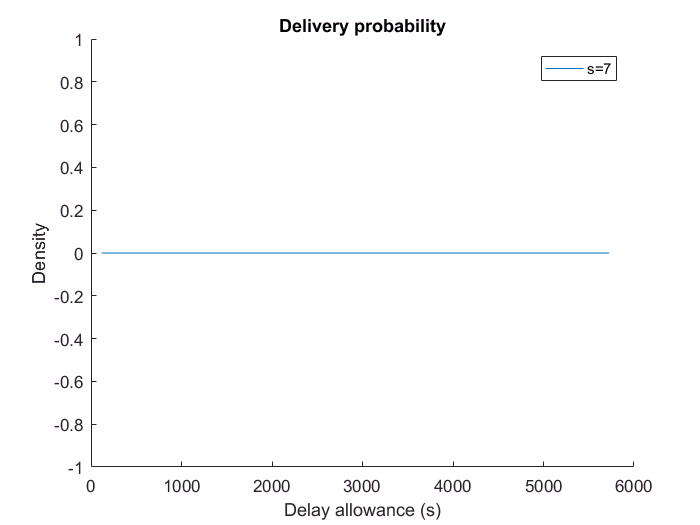

f1 = figure;
f2 = figure;
f3 = figure;
f4 = figure;
f5 = figure;

prftchU = cell(loopN, jLen, kLen);

for i = 1:loopN
    s = i*nodeF+iBase;
%     
%     figure(f1);
%     hold on;
%     bar(binVal{i});
    
    figure(f2);
    hold on
    plot([1:(test_size-1)]*lambda{i},ggpdf{i}, 'DisplayName', ['s=' num2str(s)]); 
    
    for j = 1:jLen
        c1rDelay = j*jTime;
        
        for k = 1:kLen
            Lambda = k*kLam;
            figure(f3);
            plot((1:size(conv_dly{i,j, k},2))*lambda{i},lambda{i}*cumsum(conv_dly{i,j, k}),'DisplayName',['c ' 's=' num2str(s) ' p=', num2str(expcdf(c1rDelay, Lambda))]);
            hold on;
            plot((1:size(estm_dly{i,j, k},2))*lambda{i},lambda{i}*cumsum(estm_dly{i,j, k}),'DisplayName',['e ' 's=' num2str(s) ' p=', num2str(expcdf(c1rDelay, Lambda))]);
            
            figure(f4);
            plot((1:size(conv_sto{i,j, k},2))*lambda{i}, conv_sto{i,j, k}/(s-a-c),'DisplayName',['c ' 's=' num2str(s) ' p=',num2str(expcdf(c1rDelay, Lambda))]); 
            hold on;
            plot((1:size(estm_sto{i,j},2))*lambda{i}, estm_sto{i,j, k}/(s-a-c),'DisplayName',['e ' 's=' num2str(s) ' p=',num2str(expcdf(c1rDelay, Lambda))]);
            
%                 gain{i,j, k} = - lambda{i}*cumsum(conv_dly{i,j, k}) + lambda{i}*cumsum(estm_dly{i,j, k});
%                 cost{i,j, k} = - conv_sto{i,j, k}/(s-a-c) + estm_sto{i,j, k}/(s-a-c);
%                 prftchU{i,j, k} = gain{i,j, k} .* (1-cost{i,j, k});
%                 figure(f5);
%                 plot(( 1:size(gain{i,j, k},2) )*lambda{i}, prftchU{i,j, k},'DisplayName',['s=' num2str(s) ' p=', num2str(expcdf(c1rDelay, Lambda))]); 
%                 hold on;
        end 
        
    end
    
end

% figure(f1);
% xlabel('Encounter number');
% ylabel('Delivery probability');
% title('PMF');


figure(f2);
legend('show');
xlabel('Delay allowance (s)');

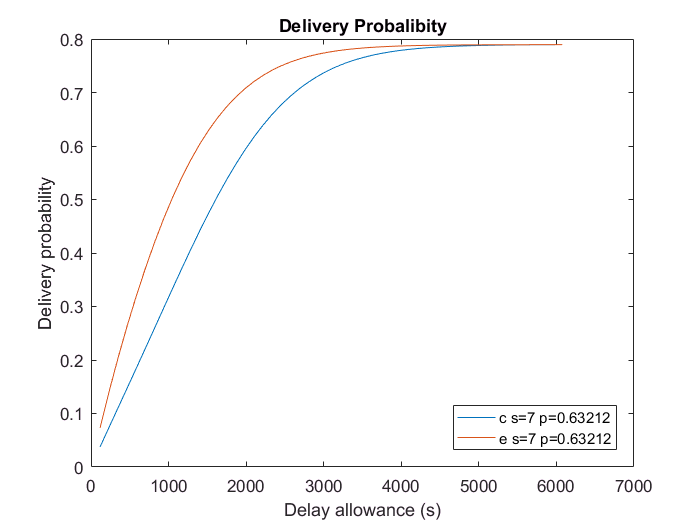

ylabel('Density');
title('Delivery probability');

figure(f3);
legend('show');
legend('Location','southeast');
xlabel('Delay allowance (s)');

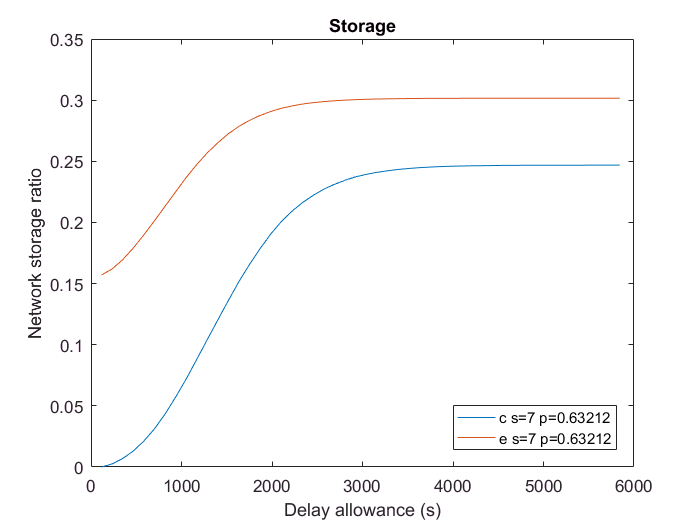

ylabel('Delivery probability');
title('Delivery Probalibity');
legend('show');

figure(f4);
legend('show');
legend('Location','southeast');
xlabel('Delay allowance (s)');

ylabel('Network storage ratio');
title('Storage');

% figure(f5);
% legend('show');
% legend('Location','northeast');
% xlabel('Delay allowance (s)');
% ylabel('Utility');
% title('Utility'); 